##     Fall Detection using Array of Infrared Sensors

Version 2,  Epocs 30

Subject 5,8, are removed as  activities are missing for this participants (missing values)

This program classify sequence data  using a long short-term memory (LSTM) network.


clear all;
input = readtable('HAR_UP_Fall_Detection_Infra_V1.csv');
%net = load("LSTM_FallDetection_Net.mat");
%net2 = net.net2;
cell_r = 1;
% Subject 5,8,9 has incomplete Infrared data, therefore discarded for this experiment

for Subject = [1,2,3,4,6,7,10,11,12,13,14,15,16,17]
    for Activity = 1:11
        for Trial = 1:3
            CompCode = 1000 * Subject + 10 * Activity + Trial;
            OutTable = input(ismember(input.CompareCode,CompCode),:);           
            InfraredArray1to6 {cell_r,1} =    [table2array(OutTable (:,1))';table2array(OutTable (:,2))';table2array(OutTable (:,3))';table2array(OutTable (:,4))';table2array(OutTable (:,5))';table2array(OutTable (:,6))'];
             cell_r = cell_r + 1 ;
        end
    end
end


fileID = fopen('Fall_Detection_Target_Infra_V1.txt');
target1 = textscan(fileID,'%s');
fclose(fileID);

target = categorical(target1{1,1});
YTest = target;


## Setup LSTM Architecture

The sequenceInputLayer size is two due to we have two features of the original signal to input inside the new LSTM

maxEpochs = 100 ;
miniBatchSize = 32  ;
sequenceLength = 1000;
initialLearnRate = 0.01;
% For binary LSTM, number of classes is 2
numClasses = 2;
% 6 infrared sensors input at a time.
inputLayer = 6;
%
layers = [ ...
    sequenceInputLayer(inputLayer)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];
options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'InitialLearnRate', initialLearnRate, ...
    'GradientThreshold', 1, ...
    'plots','training-progress', ...
    'Verbose',false);

## Training and Testing


myCell{1,1} = InfraredArray1to6;
data = [myCell{1,1},target1{1,1}];
% Data partition (NON RANDOM) (train: 70%, test: 30%)
idxL(1:size(data,1)*70/100) = 0;

idxL(1+size(data,1)*70/100:size(data,1)) = 1;

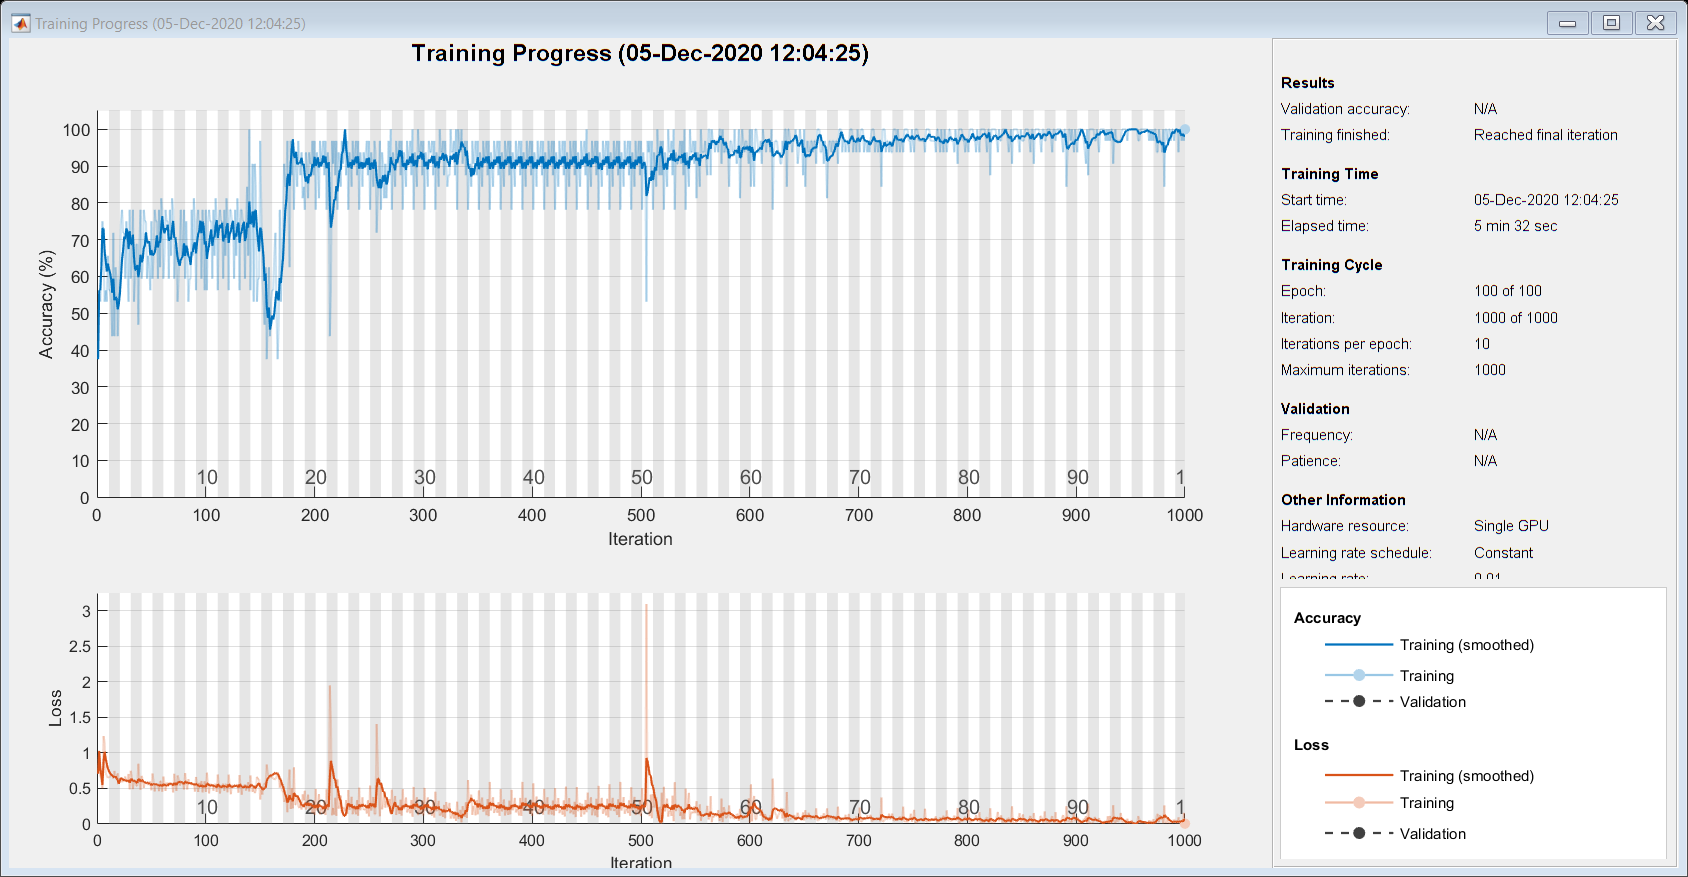

idx = logical(idxL);
% Separate to training and test data
dataTrainCombo = data(~idx,:);
dataTrainTarget = dataTrainCombo(:,2);
dataTrain = dataTrainCombo(:,1);
dataTestCombo  = data(idx,:);  
dataTest =  dataTestCombo(:,1);
dataTestTarget = dataTestCombo(:,2);

net2 = trainNetwork(dataTrain,categorical(dataTrainTarget),layers,options);

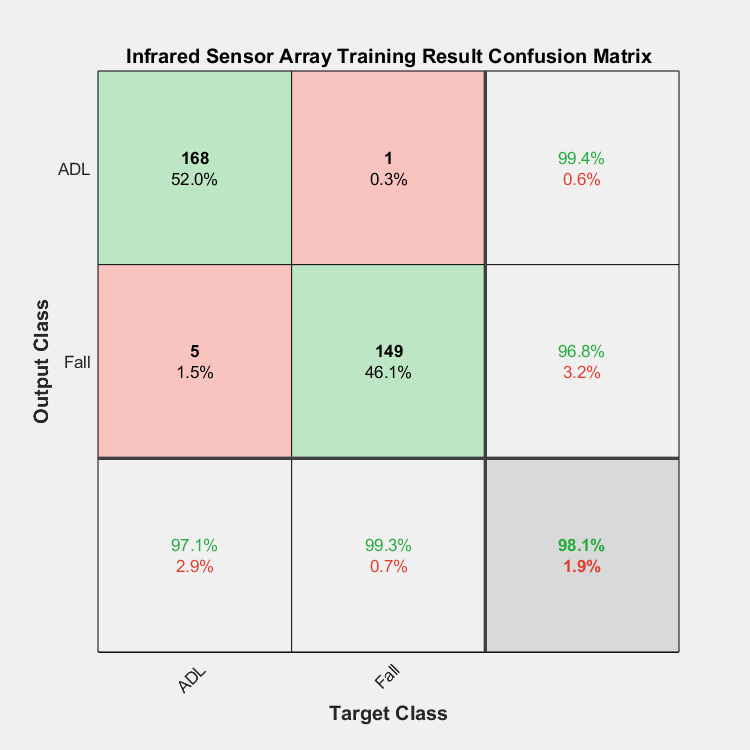

    
    
    txtTrain =  "Infrared Sensor Array Training Result";
    txtTest =   "Infrared Sensor Array Testing Result";

% Performance of the trained model from traning dataset
    trainPred = classify(net2,dataTrain);
    figure;
    plotconfusion(categorical(dataTrainTarget'),trainPred',txtTrain);

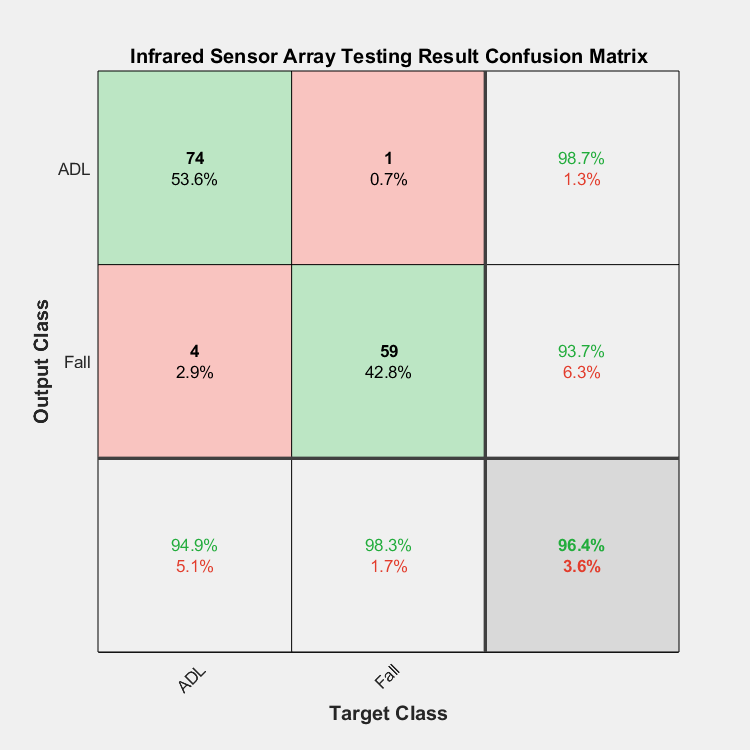

    
% Test the model with test dataset    
    testPred = classify(net2,dataTest);
    figure;
    plotconfusion(categorical(dataTestTarget'), testPred', txtTest );